#  Clase 06 >> Transformada de Fourier

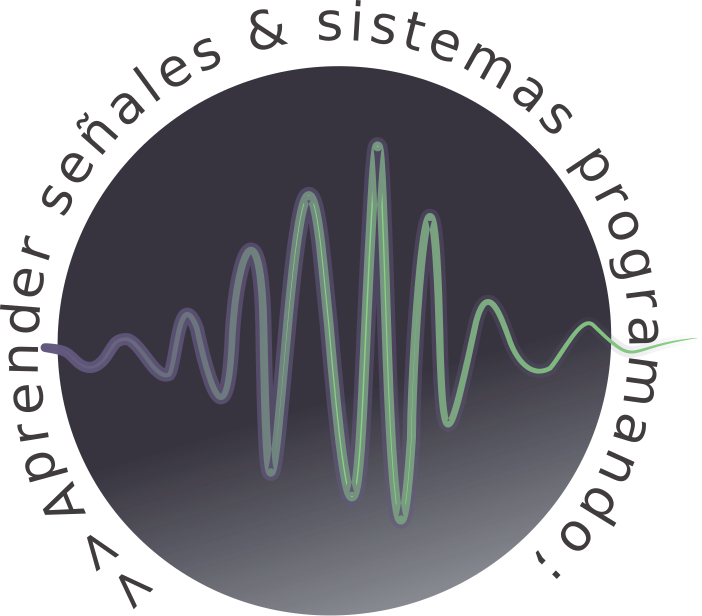

# Temario:

- Introducción.

- Condiciones de Dirichlet.

- Par de transformadas de Fourier.

- Implementación código.

- Señales con simetría par o impar.

- Propiedades.

# Introducción

Una característica importante de la representación de la serie de Fourier de una señal periódica es la descripción de dicha señal en términos del contenido de frecuencia dado por las componentes sinusoidales. Es entonces cuando surge la siguiente pregunta: **¿qué pasa con las señales no periódicas, las mismas pueden ser descriptas en términos de contenidos de frecuencia?**

La respuesta es **SI**, y la construcción analítica para hacerlo es la **transformada de Fourier**.

Como veremos, las componentes de frecuencia de señales no periódicas están definidas para todos los valores reales de la variable de frecuencia $\omega$, y no sólo para los valores discretos de $\omega$ como en el caso de una señal periódica. En otras palabras, el espectro para una señal no periódica, no es el espectro de magnitudes (a menos que la señal sea igual a la suma de sinusoides) [Kamen, 2008]. 

La siguiente tabla presenta de manera resumida lo que se introdujo en los párrafos anteriores:

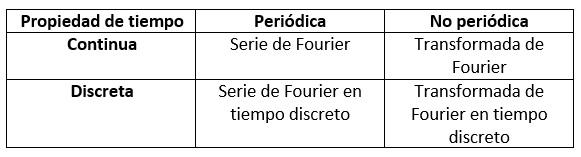

Dada una señal $x(t)$, la transformada de Fourier $X(\omega)$ de $x(t)$ está definida para que sea la función de frecuencia.

# Condiciones de Dirichlet

Dada una señal $x(t)$, la transformada de Fourier $X(j\omega)$ o $X(i\omega)$ de $x(t)$ está definida por:


$$X(j\omega)=\int_{-\infty}^{\infty}{x(t)e^{-j\omega t}dt}, \ -\infty<\omega<\infty}$$


Donde $\omega$ es la variable continua de frecuencia. Debido a la presencia de la exponencial compleja $e^{-j\omega t}$, los valores de $X(j\omega)$pueden ser complejos. Por lo tanto, en general, la transformada de Fourier$X(j\omega)$ es una función valuada en complejos de la variable de frecuencia $\omega$, y para especificar $X(j\omega)$, en general es necesario desplegar la función magnitud$\vert X(j\omega)\vert$y la función ángulo $\angle X(j\omega)$. 

La función $x(t)$, para tener transformada de Fourier $X(j\omega)$ en el sentido ordinario, tiene que cumplir con las siguientes condiciones:

- Debe ser absolutamente integrable, o sea


$$\int_{-\infty} ^{\infty} |x(t)|dt<\infty$$


- Tiene que tener a lo sumo un número finito de máximos y mínimos y un número finito de discontinuidades en cualquier intervalo finito. 

La primera condición implica que el área absoluta debajo de la gráfica de $y=x(t)$ es finita. Esto ocurre si $x(t)$decae suficientemente rápido con el tiempo.

Un ejemplo de una señal que no cumple con las condiciones de Dirichlet es una constante, como se prueba a continuación:

syms t w T % Creamos variables simbólicas.
assume(w, 'real'); assume(t,'real'); assume(T,'real'); % Asumimos que las variables w, t y t son reales.
I = int(1*exp(-1i*w*t),t,-T/2,T/2) % Calculamos la integral.

$$I = \frac{2\,\sin\left(\frac{T\,w}{2}\right)}{w}$$

L = limit(I,T,inf); % Tendemos T a infinito.
X = L % Transformada de Fourier.

$$X = \mathrm{NaN}$$

La integral no converge, entonces una señal constante no tiene transformada de Fourier en el sentido ordinario, en los apartados siguientes veremos que sí tienen transformada de Fourier en el sentido generalizado. 

Podríamos verificar la condición de Dirichlet de que la señal debe ser absolutamente integrable en cualquier intervalo finito:

I = int(1,t,-T/2,T/2); % Integral del módulo de la señal.
L = limit(I,T,inf); % Tendemos T a infinito.
L

$$L = \infty$$

**En la práctica, las señales usualmente son causales y no duran para siempre, es decir existen solo en un intervalo finito de tiempo, por lo tanto en la práctica las señales que usaremos tendrán siempre transformada de Fourier.**

# Par de transformadas de Fourier

Definimos a $X(j\omega)$como la **Transformada de Fourier (análisis)** de $x(t)$:


$$X(j\omega)=\int_{-\infty}^{\infty}x(t)e^{-j\omega t}dt$$


La **antitransformada (sintesis, reconstrucción)** de $X(j\omega)$ es:


$$x(t)=\frac{1}{2\pi}\int_{-\infty}^{\infty}X(j\omega)e^{j\omega t} d\omega$$


*Las relaciones anteriores juntas constituyen el ****par de transformadas de Fourier**** y proporcionan una trayectoria entre las representaciones del dominio del tiempo y de la frecuencia de una señal. La primera ecuación expresa *$x(t)$* en el dominio de las frecuencias y es análogo a resolverla en las componentes armónicas con frecuencia *$\omega$* que varía continuamente. Esto contrasta con la representación en serie de Fourier de una señal periódica donde las frecuencias toman valores discretos.*

# Implementación en código

Como se viene mencionando la transformada de Fourier puede utilizarse para determinar el contenido espectral de una señal, en este curso para trabajarla en  MATLAB se recurre a la utilización del paquete **Symbolic Math Toolbox** (como en el caso del cálculo de series). 

Existen comandos para calcular tanto la transformada como la transformada inversa de Fourier, `fourier(f) `e `ifourier(F)`, donde tanto `f `como `F `son objetos simbólicos que se han definido. Estos comandos en realidad utilizan el comando `int`. Por ejemplo, `fourier `utiliza el comando `int(f*exp(-i*w*x),'x',-inf,inf), `donde los límites de integración son $-\infty$ e $\infty$, y la transformada de Fourier de `f `está definida con respecto a la variable independiente $x$. Para las funciones de este texto, en general es más sencillo utilizar directamente `int `[Kamen, 2008].

## Veamos un ejemplo:


$$x\left(t\right)=\text{ }e^{−bt} u\left(t\right),b\text{ }\varepsilon \text{ }\Re$$


Esta señal tiene un comportamiento completamente diferente para los diferentes valores que tome b, se grafica la señal para los diferentes casos:

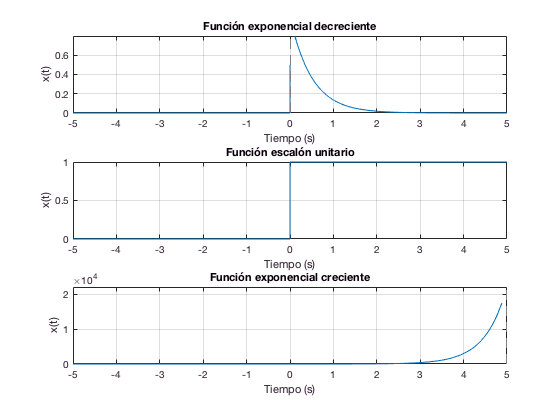

% Dibujar la función de interes
syms t 
% Primer caso:
b = 2; % b > 0    
x(t) = exp(-b*t)*heaviside(t);
subplot(3,1,1)
fplot(x)
title('Función exponencial decreciente')
ylabel('x(t)')
xlabel('Tiempo (s)')
grid on 
% Segundo caso:
b = 0;
x(t) = exp(-b*t)*heaviside(t);    
subplot(3,1,2)
fplot(x)
title('Función escalón unitario')
ylabel('x(t)')
xlabel('Tiempo (s)')
grid on     
% Tercer caso:
b = -2; % b < 0
x(t) = exp(-b*t)*heaviside(t);    
subplot(3,1,3)
fplot(x)
title('Función exponencial creciente')
ylabel('x(t)')
xlabel('Tiempo (s)')
grid on 

Ahora, se procede al cálculo de la transformada de x(t) para los diferentes casos de b:

syms t b w T
assume(t,'real'); assume(b,'real'); assume(w, 'real'); assume(T,'real');
x(t) = exp(-b*t)*heaviside(t);
% Primer caso.
assume(b < 0)
X = int(x*exp(-j*w*t),-inf,inf);
X = simplify(X)

$$X = \left\{ \begin{array}{cl} \infty & \text{ if }w=0 \end{array}\right.$$

% Segundo caso.
assume(b == 0)
X = int(x*exp(-j*w*t),-inf,inf);
X = simplify(X)

$$X = \mathrm{NaN}$$

% Tercer caso.
assume(b > 0)
X = int(x*exp(-j*w*t),t,-inf,inf);
X = simplify(X)

$$X = \frac{1}{b+w\,\mathrm{i}}$$

La transformada de x(t) sólo está definido para valores positivos de b. Se puede concluir entonces que tampoco existe la transformada ordinaria de Fourier del escalón unitario. Sí existe su transformada generalizada. Resta calcular las funciones magnitud y fase de $X(\omega)$.

Xm = simplify(abs(X),'Steps', 50)

$$Xm = \frac{1}{\sqrt{b^{2}+w^{2}}}$$

Xf = atan(imag(X)/real(X))

$$Xf = -\mathrm{atan}\left(\frac{w}{b}\right)$$

## Ejercicios de la guía "Transformada de Fourier" (script_tf_1)

Resolver el ejercicio n°1, nº2, n°3 y nº4 con un script en MATLAB.

Ejemplo, en el ejercicio nº1, usar la definicion para calcular la Transformada de Fourier de las siguientes funciones:  


$$a) f(t)=e^{-2\alpha (t-1)}u(t-1)   ,\ con \ \alpha > 0}$$


## **Ejemplo**

Se trabaja con el siguiente decaimiento sinusoidal:


$$x(t) = e ^{-at}sen(b\pi t)u(t)$$


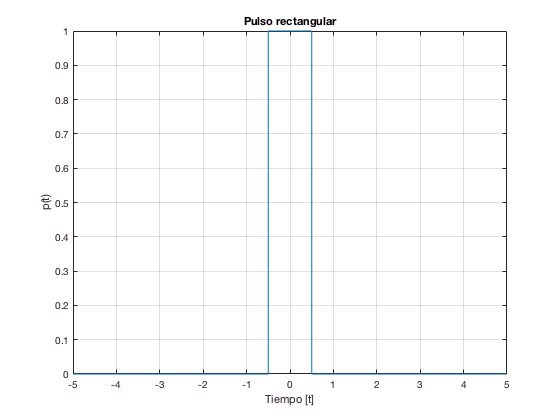

y = ejemplo
tran = y.transformada;
plo = y.ploteo;

% Calculamos su transformada de Fourier para el caso a = 2 y b = 10:
syms t w
a = 2; b = 10;
x(t) = exp(-a*t)*sin(b*sym(pi)*t)*heaviside(t)
[X] = tran(x);
X


% Ploteamos la señal temporal en un intervalo de tiempo conveniente. 
fplot(x,[0 3]); title('Señal temporal'); xlabel('Tiempo [s]'); ylabel('x(t)')
% Ploteamos, a su vez, la magnitud de la transformada de Fourier.
plo(X,0,100)

# Formas rectangular y polar de la transformada de Fourier

La transformada de Fourier es una función valuada en complejos de la varable real $\omega$, por lo tanto tiene parte real e imaginaria y, a su vez, magnitud y fase.

Su forma rectangular es:


$$X\left(\omega \right)=\int_{−\infty }^{\infty } x\left(t\right)cos\left(\omega t\right)dt−j\int_{−\infty }^{\infty } x\left(t\right)sen\left(\omega t\right)dt$$


donde la parte real de la transformada de Fourier es:


$$Re\left\lbrace X\left(\omega \right)\right\rbrace =\int_{−\infty }^{\infty } x\left(t\right)cos\left(\omega t\right)dt$$


y su parte imaginaria:


$$Im\left\lbrace X\left(\omega \right)\right\rbrace =\int_{−\infty }^{\infty } x\left(t\right)sen\left(\omega t\right)dt$$


La forma polar de la transformada de Fourier es:


$$X\left(\omega \right)=|X\left(\omega \right)|e^{j\angle X\left(\omega \right)}$$


donde $|X\left(\omega \right)|$ es la función magnitud y $\angle X\left(\omega \right)$ es la función fase de $X\left(\omega \right)$.

# Señales con simetría par o impar

Se dice que una señal $x(t)$ es **par** si $x(t)=x(-t)$, y se dice que una señal es** impar** si $x(-t)=-x(t)$. Si la señal $x(t)$ es par, se desprende que la parte imaginaria $I(\omega)$de la transformada de Fourier es cero, y la parte real $R(\omega)$ puede rescribirse como:


$$X(\omega)=2\int_{0}^{\infty}{x(t)cos(\omega t) dt}$$


Si la señal $x(t)$es impar, es decir, $x(t)=-x(-t)$para toda$t>0$, la transformada de Fourier de $x(t)$es una función de $\omega$ totalmente imaginaria, dada por:


$$X(\omega)=-j2\int_{0}^{\infty}{x(t)sen(\omega t) dt}$$


## Por ejemplo:

Dado un número fijo positivo $\tau$, sea que $p_\tau(t)$ denote el pulso rectangular de duración $t$ segundos definido por:


$$p_{\tau } \left(t\right)=\left\lbrace \begin{array}{c}
1 & si−\frac{\tau }{2}<t<\frac{\tau }{2}\\
0 & en\text{ }otro\text{ }caso
\end{array}\right.$$


% Se dibuja la función de interés.
clear all; clf;
tau = 1; % Se estable un valor fijo de tau para el ejemplo. 

$$X = \frac{2\,\sin\left(\frac{w}{2}\right)}{w}$$

syms t

Elapsed time is 10.375952 seconds.


assume(t,'real')
p(t) = heaviside(t+tau/2) - heaviside(t-tau/2);
fplot(p)

$$X = \frac{2\,\sin\left(\frac{w}{2}\right)}{w}$$

title('Pulso rectangular');

Elapsed time is 1.218666 seconds.


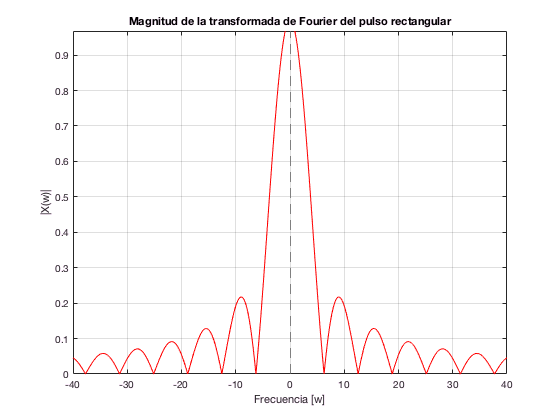

ylabel('p(t)');
xlabel('Tiempo [t]');
grid on;    
% Se calcula la transformada de Fourier de p(t).
syms w T
assume(w,'real'); assume(T,'real'); assume(abs(T)>abs(tau/2));

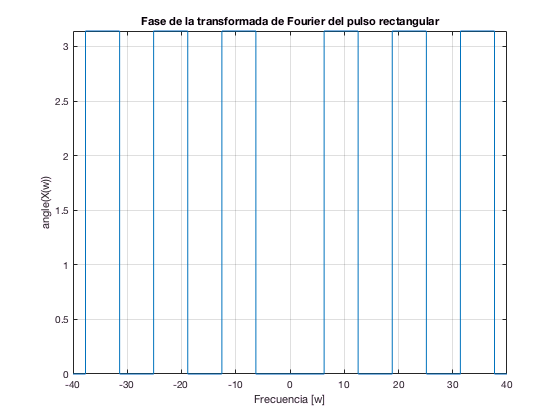

tic
% Calculamos X(w) de la forma más general posible.
I = int(p*exp(-j*w*t),t,-T/2,T/2); 
L = limit(I,T,inf);
X = simplify(L,'Steps',200)

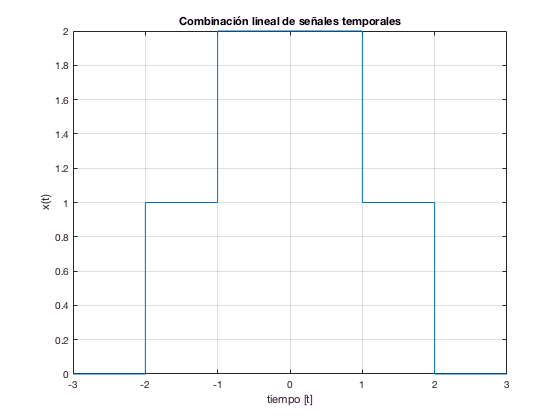

toc
tic
X = int(1*cos(w*t),t,0,tau/2); % Calculamos por usando propiedades de simetría.
X = simplify(2*X)
toc
% Se grafica el resultado.
 fplot(abs(X),[-40 40],'r')
 title('Magnitud de la transformada de Fourier del pulso rectangular');
 ylabel('|X(w)|');
 xlabel('Frecuencia [w]');
 grid on    
fplot(angle(X),[-40 40])
title('Fase de la transformada de Fourier del pulso rectangular');
ylabel('angle(X(w))');

xlabel('Frecuencia [w]');
grid on    

# Propiedades

La transformada de Fourier satisface una serie de propiedades que pueden resultar de mucha utilidad para una gran gama de aplicaciones. Las examinaremos una por una:

## Linealidad

Todos los operadores que surgen del trabajo de Fourier, sean las series o las transformadas continuas o discretas, satisfacen la condición de linealidad. Esto básicamente quiere decir que si se tienen dos señales continuas cada una con su correspondiente transformada de Fourier entonces la transformada de alguna combinación lineal de las mismas resulta en la misma combinación lineal pero de sus transformadas. Es decir, sean $f(t)$ y $g(t)$ tales que sus transformadas sean $X(\omega)
$ y $G(\omega)$:


$$f(t) \leftrightarrow F(\omega)$$



$$g(t) \leftrightarrow G(\omega)$$


Entonces:


$$F\{\alpha f(t)+ \beta g(t)\} \leftrightarrow \alpha F(\omega) + \beta G(\omega)$$


Por ejemplo, si consideramos la siguiente señal:

syms t
assume(t,'real')
x(t) = (heaviside(t+2)-heaviside(t-2)) + (heaviside(t+1)-heaviside(t-1));
fplot(x,[-3 3]); grid on; ylabel('x(t)'); xlabel('tiempo [t]'); title('Combinación lineal de señales temporales')

Se ve que la misma puede considedarse como la suma de dos pulsos unitarios, una señal cuyo valor es 1 en el intervalo temporal [-2,2] mientras que la otra vale 1 en el [-1,1].

Se calcula la transformada de Fourier de la señal resultante por definición y usando la propiedad de linealidad; se comaparan los resultados.

syms t w
assume(w,'real');
assume(t,'real');

% Calculo usando propiedad de linealidad.

$$K(w) = \frac{2\,\sin\left(2\,w\right)+2\,\sin\left(w\right)}{w}$$

F(w) = int(1*exp(-j*w*t),t,-2,2);
G(w) = int(1*exp(-j*w*t),t,-1,1);

K(w) = F + G;

$$H(w) = \frac{2\,\sin\left(2\,w\right)+2\,\sin\left(w\right)}{w}$$

K = simplify(K)

% Cálculo por definición.

ans =    1


H(w) = int(1*exp(-j*w*t),t,-2,-1)+int(2*exp(-j*w*t),t,-1,1)+int(1*exp(-j*w*t),t,1,2);
H = simplify(H)

% Se comprueba la igualdad.
isequal(H,K)

 La linealidad queda comprobada de este modo.

## Derivación con respecto al tiempo

Se supone que se tiene una función temporal con su respectiva transformada de Fourier:


$$x(t) \leftrightarrow X(\omega)$$


La derivada de orden n de la señal $x(t)$tiene entonces la siguiente transformada:


$$\frac{d^n}{dt^n} \{x(t)\} \leftrightarrow (j\omega)^nX(\omega)$$


Comprobemos la propiedad mediante un ejemplo:

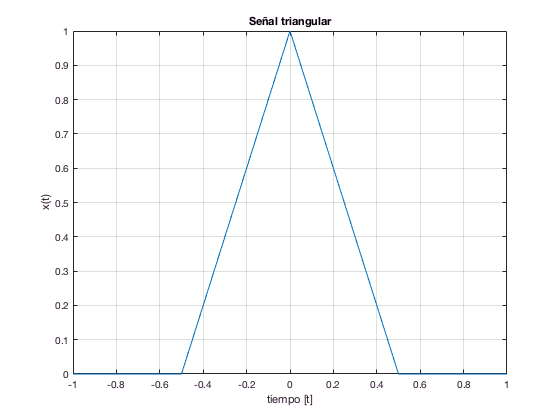

% Graficamos la señal triangular.
syms t w
assume(t,'real'); assume(w,'real');
tau = 1;
x(t) = (1 - 2*abs(t)/tau)*(heaviside(t+tau/2)-heaviside(t-tau/2)); % señal triangular.
fplot(x,[-1 1]); grid on; ylabel('x(t)'); xlabel('tiempo [t]'); title('Señal triangular')

v(t) = diff(x,t); % derivada de x.
% Se calcula V(w) por definición.
syms T
assume(T,'real'); assume(abs(T) > abs(tau/2));
I = int(v*exp(-j*w*t),t,-T/2,T/2);
L = limit(I,T,inf);
V1 = simplify(L,'Steps',50) % simplificamos expresion.

$$V1 = \frac{8\,{\sin\left(\frac{w}{4}\right)}^{2}\,\mathrm{i}}{w}$$

% Calculamos V(w) utilizando la propiedad. 
I = int(x*exp(-j*w*t),t,-T/2,T/2);
L = limit(I,T,inf);
X = simplify(L,'Steps',50);
V2 = (j*w)*X % Usamos la propiedad

$$V2 = \frac{8\,{\sin\left(\frac{w}{4}\right)}^{2}\,\mathrm{i}}{w}$$

isequal(V1,V2) % Comprobamos igualdad.

ans =    1


## Corrimiento temporal

El corrimiento temporal de una señal continua $x(t)$ que tiene transformada de Fourier $X(\omega)$ produce lo siguiente:


$$x(t-c) \leftrightarrow X(\omega) e^{-j\omega c}$$


con c siendo un número real positivo o negativo. 

Comprobemos la propiedad mediante un ejemplo:

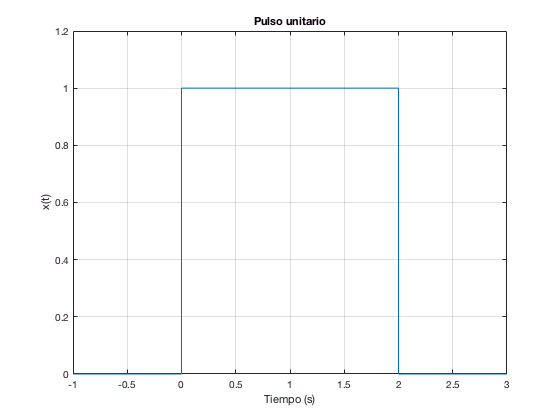

syms t w
assume(t,'real'); assume(w,'real')
x(t) = 1*heaviside(t+1)*heaviside(-t+1);
y(t) = x(t-1);
fplot(y, [-1 3]); ylim([0 1.2]); grid on; title('Pulso unitario'); xlabel('Tiempo (s)');
ylabel('x(t)');

La señal $y(t)$ es un desplazamiento de la señal $x(t)$ una unidad de tiempo hacia la derecha. 

X = int(x*exp(-j*w*t),t,-inf,inf);
X = simplify(X,'steps',100)

$$X = \frac{2\,\sin\left(w\right)}{w}$$

Y = int(y*exp(-j*w*t),t,-inf,inf);
Y = simplify(Y,'steps',100)

$$Y = \frac{\sin\left(2\,w\right)-2\,{\sin\left(w\right)}^{2}\,\mathrm{i}}{w}$$

Y2 = X*exp(-j*w);
Y2 = simplify(Y2,'Steps',200)

$$Y2 = \frac{\sin\left(2\,w\right)-2\,{\sin\left(w\right)}^{2}\,\mathrm{i}}{w}$$

isequal(Y,Y2) % comprobamos la propiedad. 

ans =    1


## Corrimiento frecuencial 

El producto de una exponencial compleja con una señal $x(t)$ en el dominio temporal corresponde a un desplazamiento en el dominio de las frecuencias. En otras palabras:


$$x(t)e^{j\omega _{0} t} \leftrightarrow X(\omega - \omega_{0})$$


Veamos el siguiente ejemplo:

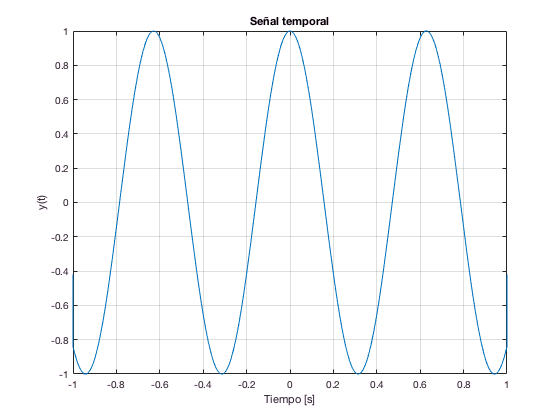

syms t w
w0 = 10; % rad/s. 
y(t) = cos(w0*t)*(heaviside(t+1)-heaviside(t-1));
fplot(y,[-1 1]); title('Señal temporal'); xlabel('Tiempo [s]'); ylabel('y(t)'); grid on;

La señal anterior puede pensarse como un pulso cuyo intervalo va desde $t = -1$ hasta $t = 1$, multiplicado por un coseno que oscila a cierta frecuencia f. 

Utilizando la identidad de Euler para los cosenos junto con la propiedad antes comentada podemos afirmar que:


$$x(t)cos(\omega_{0}t) \leftrightarrow \frac{1}{2}[X(\omega + \omega _{0}) + X(\omega - \omega _{0})]$$


En nuestro caso $x(t)$ es el pulso unitario.

% Se calcula transformada de Fourier:
Y = int(y*exp(-j*w*t),t,-inf,inf);
Y = simplify(Y,'Steps',300)

$$Y = \left\{ \begin{array}{cl} \frac{\sin\left(w-10\right)}{w-10}+\frac{\sin\left(w+10\right)}{w+10} & \text{ if }w\neq 0 \end{array}\right.$$

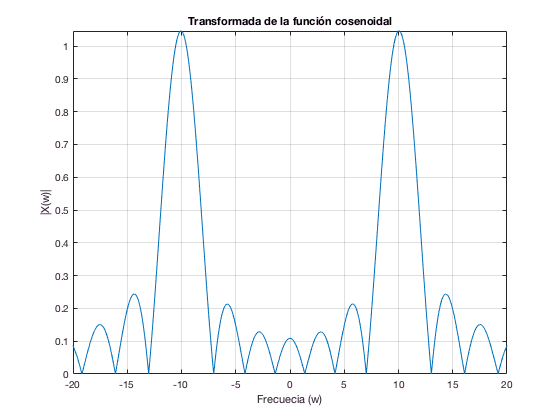

fplot(abs(Y),[-20 20]); title('Transformada de la función cosenoidal'); xlabel('Frecuecia (w)');
ylabel('|X(w)|'); grid on;

## Dualidad

Para desarrollar este concepto vamos a considerar una señal con su correspondiente transformada de Fourier:


$$x(t) \leftrightarrow X(\omega)$$


Si hacemos el siguiente cambio de variable $t = \omega$, obtenemos la señal de tiempo continuo $X(t)$. La dualidad establece que la transformada de Fourier de la señal anterior es igual a $2\pi x(- \omega)$. Entonces tenemos que:


$$X(t) \leftrightarrow 2\pi x(-\omega)$$


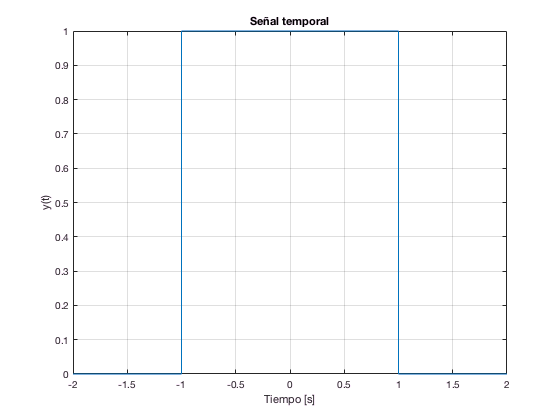

syms t w
x(t) = (heaviside(t+1) - heaviside(t-1));
fplot(x,[-2 2]); title('Señal temporal'); xlabel('Tiempo [s]'); ylabel('y(t)'); grid on;

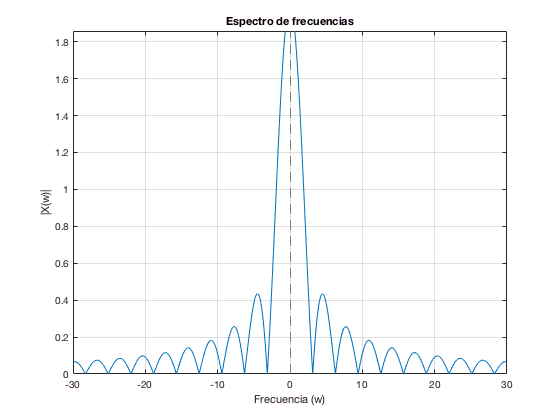

X(w) = fourier(x);
X = simplify(X,'Steps',300);
fplot(abs(X),[-30,30]); title('Espectro de frecuencias'); xlabel('Frecuencia (w)');
ylabel('|X(w)|'); grid on;

% Establecemos el cambio de variable w = t.
x2 = X(t)

$$x2 = \frac{2\,\sin\left(t\right)}{t}$$

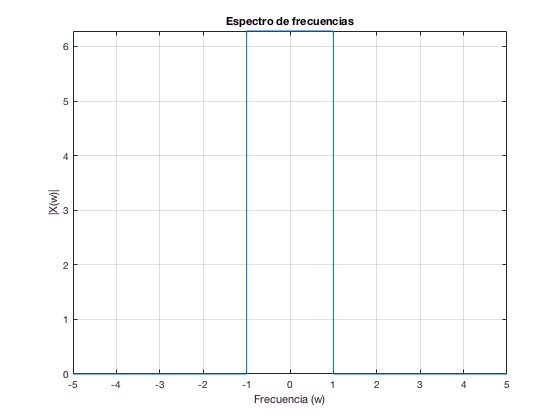

X2 = fourier(x2);
fplot(X2); title('Espectro de frecuencias de X(t)'); xlabel('Frecuencia (w)');
ylabel('|2*pi*x(-w)|'); grid on;

## Teorema de Parseval

Suponemos que contamos con una señal con su correspondiente transformada de Fourier:


$$x(t) \leftrightarrow X(\omega)$$


El teorema de Parseval establece la siguiente relación entre la energía de la señal temporal y la integral del cuadrado de la magnitud de su transformada de Fourier: 


$$\int _{-\infty}  ^ { \infty} x^2(t)dt = \frac{1}{2\pi}\int _{-\infty}  ^ { \infty} |X(\omega)|^2d\omega$$
   

## Transformada de Fourier generalizada

En el sentido ordinario, hay funciones que no tienen transformada de Fourier, ya que al ser esta misma una integral hay casos en las cuales ésta no converge. Ejemplos de este tipo de señales son el escalón unitario $u(t)$ y las funciones trigonométricas elementales $sen(\omega_0t)$ y $cos(\omega_{0}t)$. Pero éstas son señales que a menudo las usamos en señales y sistemas por lo cual resulta muy conveniente que las mismas tengan transformada de Fourier, ya que de esa manera tendríamos muy limitado el uso de la herramienta. 

Algunas transformadas con las que vamos a trabajar sin demostrarlas son:


$$\delta(t) \leftrightarrow 1$$


syms t
x = dirac(t);
X = fourier(x)

$$X = 1$$

Por la propiedad de dualidad:


$$1 \leftrightarrow 2\pi\delta(\omega)$$


x = sym(1);
X = fourier(x)

$$X = 2\,\pi \,\delta (w)$$

Utilizando la última transformada y la propiedad de corrimiento frecuencial obtenemos las transformadas del seno y del coseno. 


$$cos(\omega_0t) \leftrightarrow \pi[\delta(\omega + \omega_0) + \delta(\omega - \omega_0)]$$



$$sen(\omega_0t) \leftrightarrow j\pi[\delta(\omega + \omega_0) - \delta(\omega - \omega_0)]$$


x = cos(2*t);
X = fourier(x)

$$X = \pi \,\left(\delta (w-2)+\delta (w+2)\right)$$

## Convolución

Existe una propiedad muy importante que establece que la transformada de Fourier de la convolución de dos señales temporales es la multiplicación de sus respectivas transformadas. Es decir:


$$x(t)*v(t) \leftrightarrow X(\omega)Y(\omega)$$


Esta propiedad es muy útil para determinar la relación entre la entrada y la salida de un sistema lineal e invariante en el tiempo continuo. 

syms t w
assume(t,'real'); assume(w,'real');
x(t) = heaviside(t+1)*heaviside(-t+1);
h(t) = 2*heaviside(t+1)*heaviside(-t+1);
% si y(t) es el resultado de la convolucion entre x(t) y h(t) entonces puedo calcular sus respectivas 
% transformadas, multiplicarlas y al resultado antitransformarlo.
X = fourier(x);
X = simplify(X,'Steps',50)

$$X = \frac{2\,\sin\left(w\right)}{w}$$

H = fourier(h);
H = simplify(H,'Steps',50)

$$H = \frac{4\,\sin\left(w\right)}{w}$$

Y = X*H

$$Y = \frac{8\,{\sin\left(w\right)}^{2}}{w^{2}}$$

y = ifourier(Y,t);
y = simplify(y,'Steps',300)

$$y = \left|t-2\right|+\left|t+2\right|-2\,\left|t\right|$$

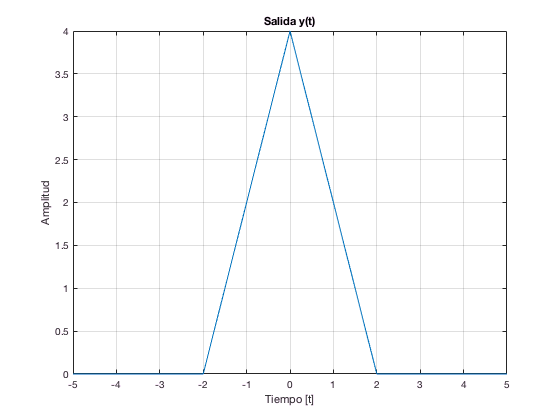

fplot(y); title('Salida y(t)'); xlabel('Tiempo [t]'); ylabel('Amplitud'); grid on

## Ejercicios de la guía "Transformada de Fourier" (script_tf_2)

Resolver el ejercicio n°7 y nº8 con un script en MATLAB.

Ejemplo, en el ejercicio nº7, usar la definicion de la antitransformada de Fourier para hallar $x(t)$:  


$$X(j\omega)= \left\lbrace
\begin{array}{ll}
\text{2\text{  } si \,0 \le \omega \le 2 \\
\text{-2\text{  } si \,-2 \le \omega \le 0 \\
\text{0 \text{  } si \,|\omega| > 2 \\
\end{array}
\right. 
\end{equation}, $$


y = script_tf_2()

y =         Ejercicio7: [1x1 sym]
        Ejercicio8: [1x1 sym]
    Comentario_ej8: 'Al calcular a mano la antitransformada, se pueden usar las propiedades …'


## Propuesta de ejercicio

Hacer un programa con interfaz de usuario que calcule la transformada de Fourier de una señal temporal cualquiera y en el cual puedan visualizarse las gráficas de la señal temporal, de la  función magnitud de la transformada y de la función fase de la transformada.

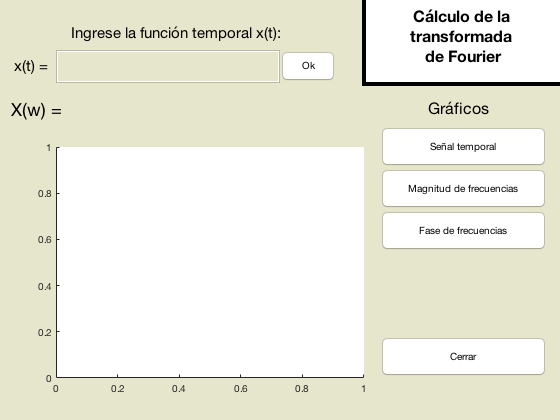

transformadaDeFourier()    

## Referencias

- Kamen, Edward W., and Bonnie S. Heck. ***Fundamentos de señales y sistemas usando la Web y Matlab***. Pearson Prentice-Hall, 2008.